# Импорт данных в MATLAB

Обзор различных методов получения данных непосредственно из MATLAB

## Работа с текстовыми файлами и таблицами

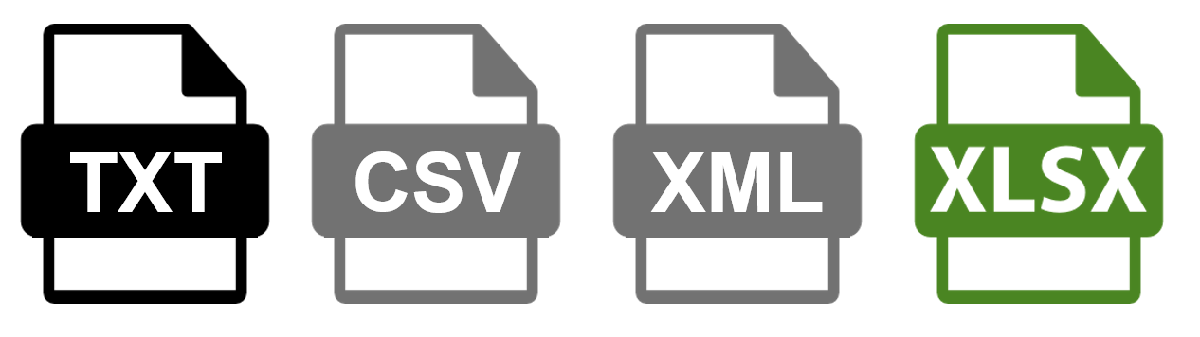

- Поддерживаются любые текстовые файлы, в том числе специализированные форматы (CSV, XML, Excel, ...)

- Удобный импорт таблиц

### Интерактивный импорт таблиц

В окне инструмента можно настроить параметры импорта и сгенерировать MATLAB код для автоматизации

uiimport('tsunamis.csv')

### Импорт таблиц с помощью команды 'readtable'

Команда `readtable` работает с любыми текстовыми, CSV и Excel-файлами, в которых хранятся табличные данные. Имеет большое количество настроек импорта.

tsunamis = readtable('tsunamis.csv')

tsunamis = 162×20 table
    Latitude    Longitude    Year    Month    Day    Hour    Minute    Second    ValidityCode           Validity            CauseCode              Cause               EarthquakeMagnitude         Country                       Location                  MaxHeight    IidaMagnitude    Intensity    NumDeaths    DescDeaths
    ________    _________    ____    _____    ___    ____    ______    ______    ____________    _______________________    _________

## Чтение бинарных файлов

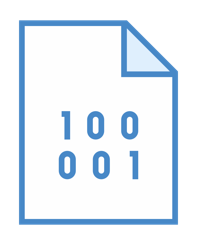

Зная формат хранения данных, можно прочитать любой бинарный файл

fileID = fopen('data.bin');
data = fread(fileID, [4, Inf], 'double')

data =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


fclose(fileID);

## Работа с медиа-файлами

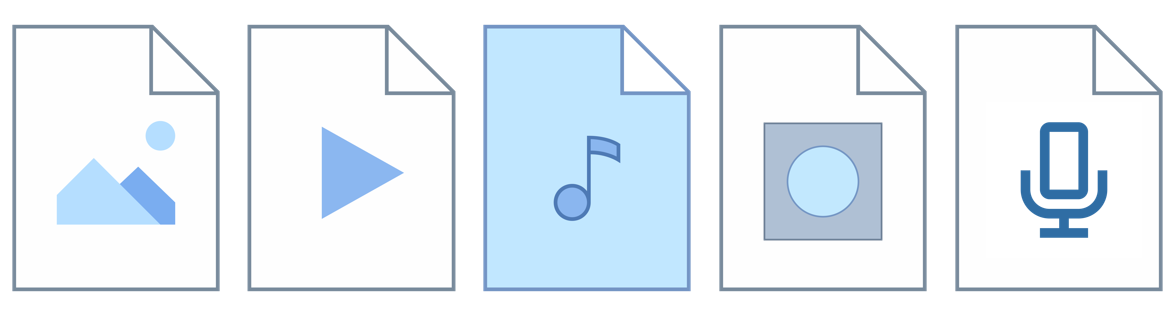

- Чтение видео, аудиофайлов изображений

- Поддерживается работа с камерами

- Запись звука с микрофона

### Импорт изображений

Считаем изображение с диска и отобразим в MATLAB

img = imread('MATLAB-logo.jpg')

img = 564×614×3 uint8 array
img(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   2

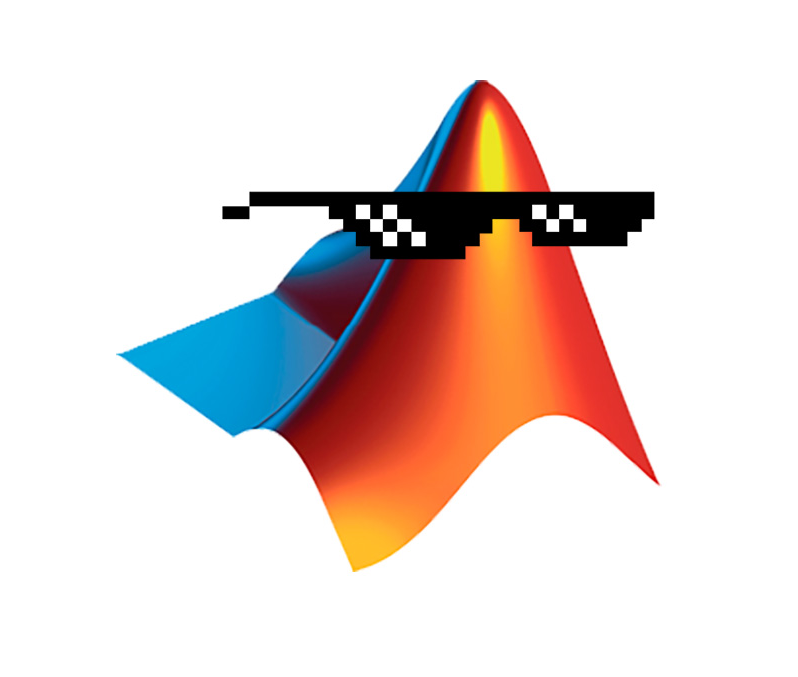

imshow(img)

### Работа с вебкамерой

Требуется установить [пакет поддержки](https://www.mathworks.com/matlabcentral/fileexchange/45182).

Подключаемся к камере и выводим картинку с неё

cam = webcam()
preview(cam)

Сделать снимок с камеры

img = snapshot(cam);
imshow(img)

## Подключение к базам данных

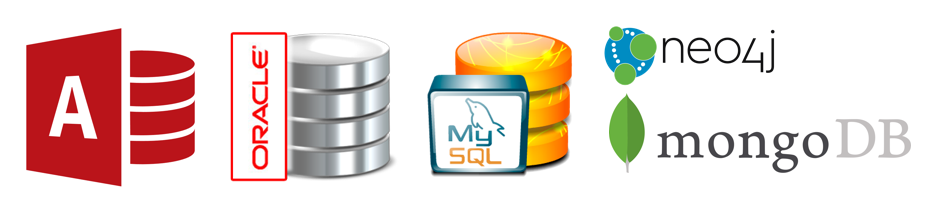

C [Database Toolbox](https://www.mathworks.com/products/database.html) поддерживаются базы данных:

- Реляционные

- Графовые

- Документоориентированные

[OPC Toolbox](https://www.mathworks.com/products/opc.html) позволяет работать с промышленными БД.

## Получение данных из интернета

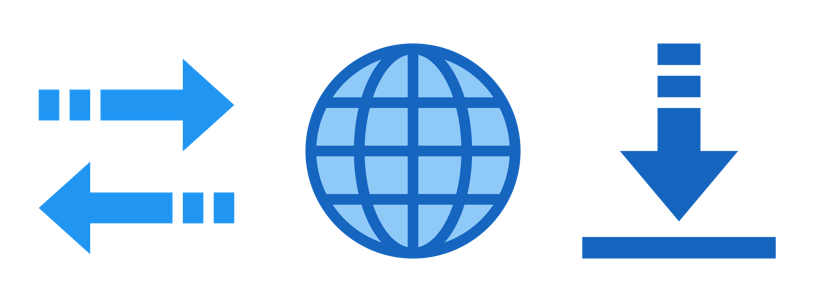

### Базовые возможности

MATLAB умеет:

- Скачивать файлы

- Обращаться к веб-сервисам (GET, POST, ...)

- Работать с FTP, Email

Обратимся к сервису [RESTCountries](https://restcountries.eu), который бесплатно предоставляет информацию о странах.

Получим информацию о России

data = webread('https://restcountries.eu/rest/v2/name/russia')

data = struct with fields:
              name: 'Russian Federation'
    topLevelDomain: {'.ru'}
        alpha2Code: 'RU'
        alpha3Code: 'RUS'
      callingCodes: {'7'}
           capital: 'Moscow'
      altSpellings: {5×1 cell}
            region: 'Europe'
         subregion: 'Eastern Europe'
        population: 146599183
            latlng: [2×1 double]
           demonym: 'Russian'
              area: 17124442
              gini: 40.1000
         timezones: {9×1 cell}
           borders: {14×1 cell}
        nativeName: 'Россия'
       numericCode: '643'
        currencies: [1×1 struct]
         languages: [1×1 struct]
      translations: [1×1 struct]
              flag: 'https://restcountries.eu/data/rus.svg'
     regionalBlocs: [1×1 struct]
              cioc: 'RUS'


Получим название и столицу каждой страны в мире (нужно передать дополнительный параметр `fields`)

data = webread('https://restcountries.eu/rest/v2/all', 'fields', 'name;capital')

data = 250×1 struct array with fields:
    name
    capital


### Продвинутая работа с WEB

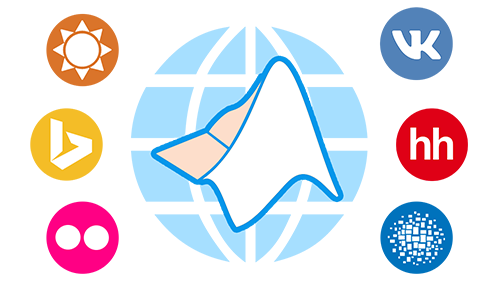

Библиотека для работы с веб-сервисами: [MATLAB WEB API](https://www.mathworks.com/matlabcentral/fileexchange/68611)

## Работа с оборудованием

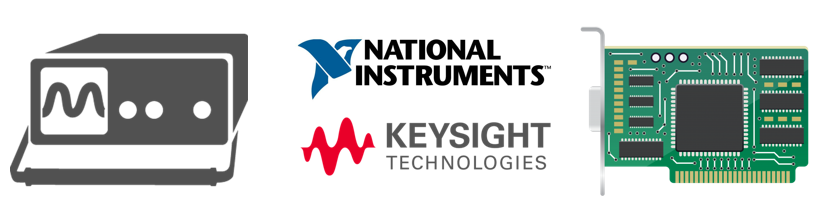

MATLAB может работать с большим количеством оборудования, в т.ч. с измерительными инструментами и платами сбора данных.

### Работа с измерительным оборудованием

MATLAB поддерживает протоколы:

- Serial

- UDP, TCP/IP

С [Instrument Control Toolbox](https://www.mathworks.com/products/instrument.html):

- IVI, VXI, GPIB, VISA, LXI, PXI

- I2C, SPI, MODBUS

- Bluetooth

С [Vehicle Network Toolbox](https://www.mathworks.com/products/vehicle-network.html):

- CAN, CAN FD

- XCP, J1939

### Работа с устройствами сбора данных (DAQ)

[Data Aquisition Toolbox](https://www.mathworks.com/products/daq.html) позволяет писать свои драйвера и работать с интерфейсами:

- USB

- PCI/PCI-Express

- PXI/PXI-Express

## Сбор данных с микроконтроллеров

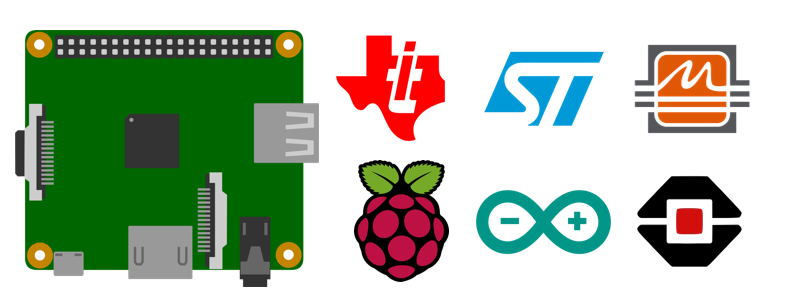

MATLAB работает с большим количеством микроконтроллеров от разных производителей.

Для работы с профессиональными контроллерами требуется [Embedded Coder](https://www.mathworks.com/products/embedded-coder.html).

### Работа с Arduino

Для работы с Arduino наобходимо установить [пакет поддержки](https://www.mathworks.com/matlabcentral/fileexchange/47522).

Получим данные с Arduino Uno. На базе этой платы реализовано устройство с RGB-светодиодом и датчиком освещенности. [Подробнее об устройстве](https://www.mathworks.com/matlabcentral/fileexchange/57168).

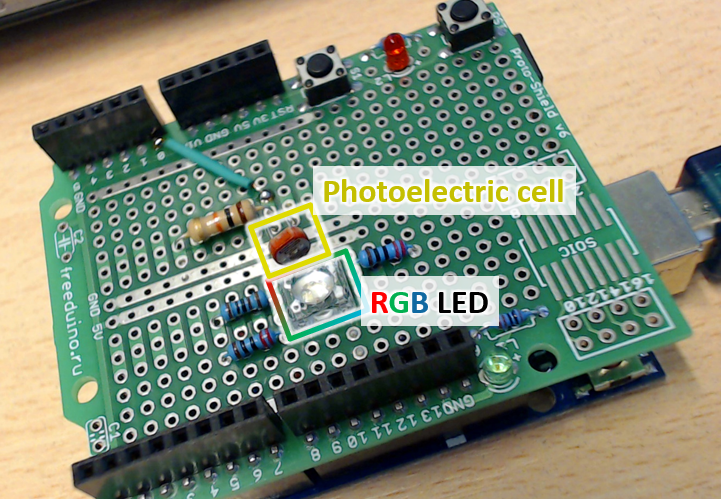

Подключимся к плате

a = arduino

a =   arduino with properties:

                    Port: 'COM3'
                   Board: 'Uno'
           AvailablePins: {'D2-D13', 'A0-A5'}
               Libraries: {'I2C', 'Servo', 'SPI'}


Снимем значение напряжения с датчика освещенности

a.readVoltage('A0')

ans = 3.7488

Построим график освещенности в реальном времени

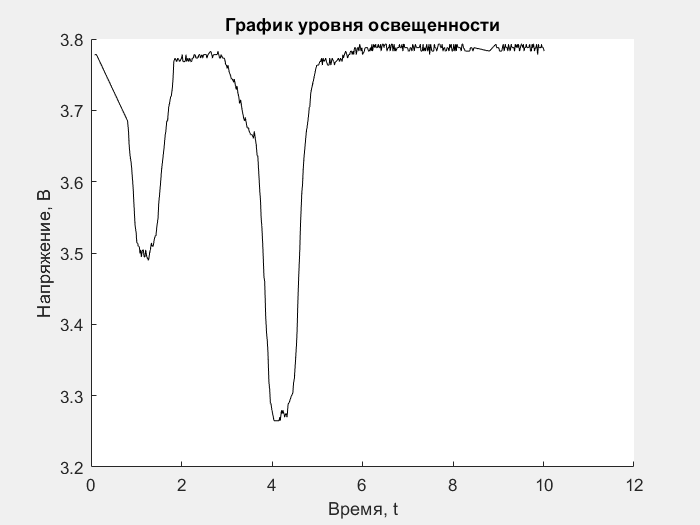

f = figure('visible','on');
h = animatedline();
tic();
t = 0;
title('График уровня освещенности')
xlabel('Время, t')
ylabel('Напряжение, В')
while isvalid(f) && t < 10
    t = toc();
    v = a.readVoltage('A0'); % Аналаговый вход A0
    addpoints(h, t, v);
    drawnow limitrate
end

Выберем цвет

color = 'white';
c_list = struct('red', [1 0 0], 'green', [0 1 0], 'blue', [0 0 1], 'white', [1 1 1], 'black', [0 0 0]);
color = c_list.(color);
a.writePWMDutyCycle('D9', 1 - color(1));  % Цифровой выход D9
a.writePWMDutyCycle('D10', 1 - color(2)); % Цифровой выход D10
a.writePWMDutyCycle('D11', 1 - color(3)); % Цифровой выход D11

## Получение данных с датчиков телефона

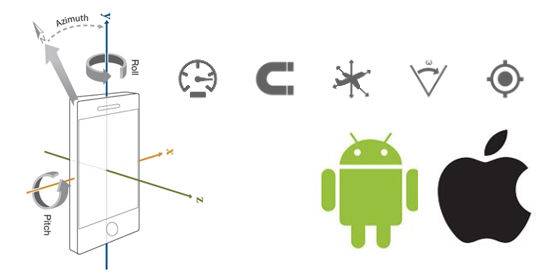

На телефон нужно установить приложение [MATLAB Mobile](https://www.mathworks.com/products/matlab-mobile.html). На компьютер нужно установить пакет поддержки для датчиков телефона: [Android](https://www.mathworks.com/matlabcentral/fileexchange/47618), [iOS](https://www.mathworks.com/matlabcentral/fileexchange/51235).

Компьютер и смартфон должны находится в одной сети (например, подключены к одному WiFi-роутеру).

Запускаем коннектор

connector on password

DNS name: WINDOWSPCIP
IP address: 192.168.56.110
Use this link to test the MATLAB Connector:
<a href="http://WINDOWSPCIP:31415/">http://WINDOWSPCIP:31415/</a>


If the test is successful, but MATLAB Mobile cannot connect, 
your computer might have multiple IP addresses.  To determine
the correct one, see Determining the DNS Name or IP Address of a Computer.



На телефоне в MATLAB Mobile нужно подключиться к компьютеру по IP с паролем *password.*

После этого подключаемся к датчикам телефона

m = mobiledev

m = mobiledev with properties:

                   Connected: 1
                     Logging: 0
            InitialTimestamp: ''

   AccelerationSensorEnabled: 0
AngularVelocitySensorEnabled: 0
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 0
       PositionSensorEnabled: 0

Supported functions

На телефоне выбираем датчик **Orientation** и нажимаем **START.**

Считываем углы ориентации телефона с гироскопа

angles = m.Orientation

angles =  -169.4065  -28.4672    8.5426


Строим график угла наклона в реальном времени

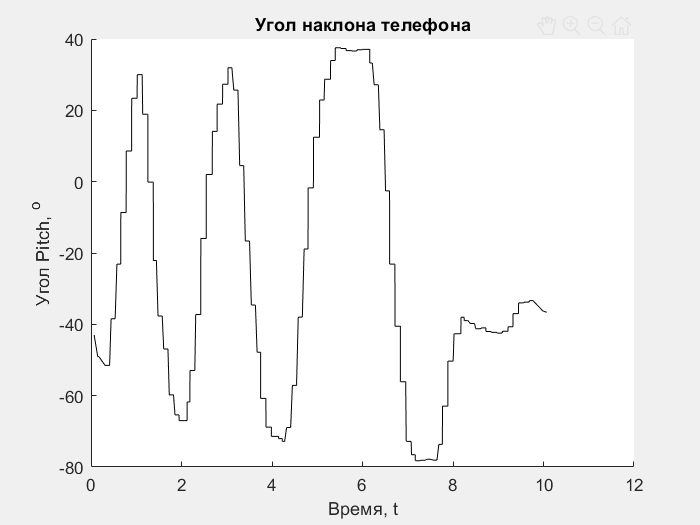

f = figure('visible','on');
h = animatedline();
tic();
t = 0;
title('Угол наклона телефона')
xlabel('Время, t')
ylabel('Угол Pitch, ^o')
while isvalid(f) && t < 10
    t = toc();
    angle = m.Orientation(2); % Pitch
    addpoints(h, t, angle);
    drawnow limitrate
end

*Pavel Roslovets, *[*ETMC Exponenta*](https://exponenta.ru/)* © 2018*